スマートフォンIMUデータを2Dでプロットします

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
sensor_data_path = fullfile("MobileSensorData", "sensorlog_20221210_151358.mat");
% sensor_data_path = fullfile("MobileSensorData", "sensorlog_20220813_105547.mat");
Hz = 30;
DynamicShowLength = 30*6; %frames，30Hz 
offset = 30*0+1; % Show area start point
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
df=importdata(sensor_data_path);
[DataFramesNum, ColNum] = size(df.Acceleration);

ShowAreaStart = offset/Hz;
ShowAreaEnd = (offset+DynamicShowLength)/Hz;
x = linspace(ShowAreaStart, ShowAreaEnd, DynamicShowLength+1);

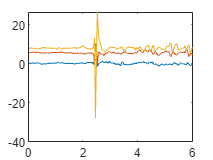

y1 = df.Acceleration.X(offset:offset+DynamicShowLength);
y2 = df.Acceleration.Y(offset:offset+DynamicShowLength);
y3 = df.Acceleration.Z(offset:offset+DynamicShowLength);
% y1 = df.AngularVelocity.X(offset:offset+DynamicShowLength);
% y2 = df.AngularVelocity.Y(offset:offset+DynamicShowLength);
% y3 = df.AngularVelocity.Z(offset:offset+DynamicShowLength);
%plot(axisX,posiX,axisX,posiY,axisX,posiZ);
plot(x,y1,x,y2,x,y3);